# 1D advection


$$\frac{\partial\psi}{\partial t}=-u\frac{\partial\psi}{\partial x}$$


Setup parameters

h = 1.5;
dt = 0.5;
X = 768;
T = 1024;
x = 0:h:X;
l = length(x);
y = zeros(1, l);
for i = 1:length(x)
    if x(i) > 49.9 && x(i) < 110.1
        y(i) = 100*sin(pi*(x(i)-50)/60);
    end
end

### Runge-Kutta Sequential Results

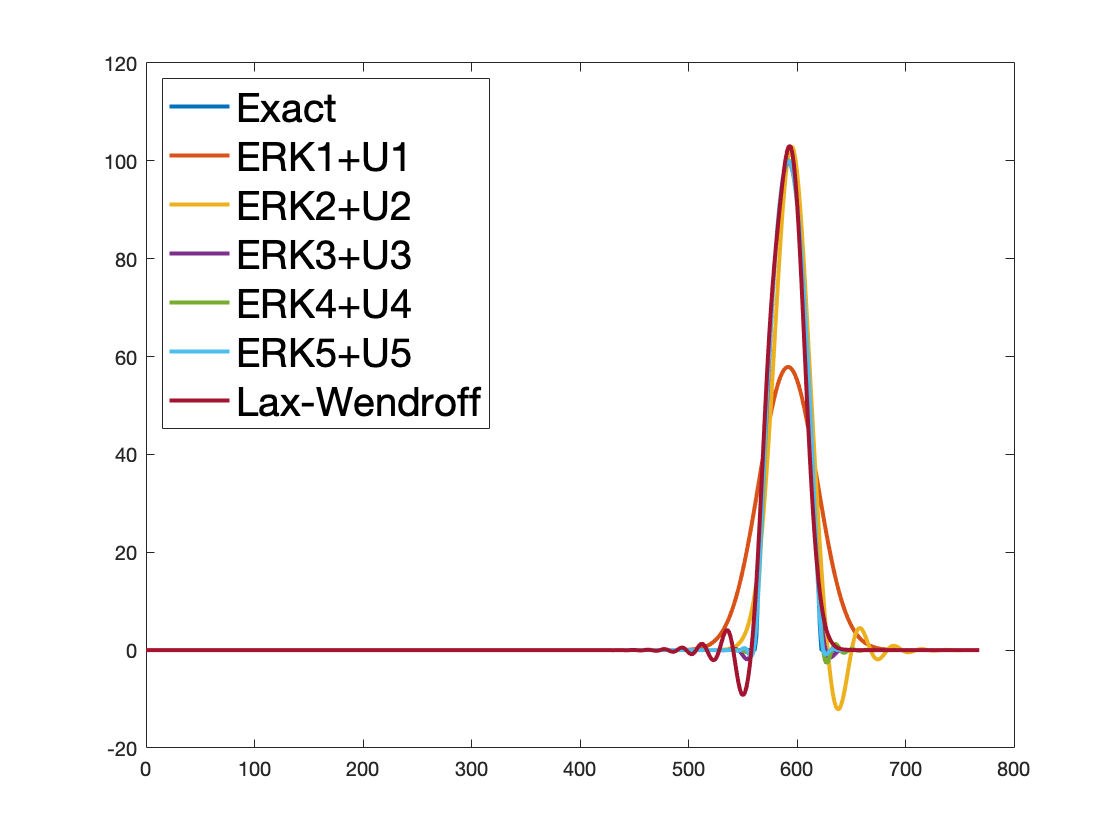

exact = zeros(1, l);
for i = 1:length(x)
    if x(i) > 49.9+512 && x(i) < 110.1+512
        exact(i) = 100*sin(pi*(x(i)-50-512)/60);
    end
end
figure
set(gca, 'FontSize', 20)
plot(x,exact, "LineWidth", 2)
hold on
RK1 = y; RK2 = y; RK3 = y; RK4 = y; RK5 = y; LW = y;
for i = 1:T
    RK1 = ERK1_U1(RK1, h, dt);
    RK2 = ERK2_U2(RK2, zeros(1,l), h, dt);
    RK3 = ERK3_U3(RK3, h, dt);
    RK4 = ERK4_U4(RK4, h, dt);
    RK5 = ERK5_U5(RK5, h, dt);
    LW = Lax_Wendroff(LW, zeros(1,l), h, dt);
end
plot(x,RK1, "LineWidth", 2)
plot(x,RK2, "LineWidth", 2)
plot(x,RK3, "LineWidth", 2)
plot(x,RK4, "LineWidth", 2)
plot(x,RK5, "LineWidth", 2)
plot(x, LW, "LineWidth", 2)
legend({'Exact', 'ERK1+U1', 'ERK2+U2', 'ERK3+U3', 'ERK4+U4', 'ERK5+U5', 'Lax-Wendroff'}, 'Location', 'northwest', 'FontSize', 20)
hold off

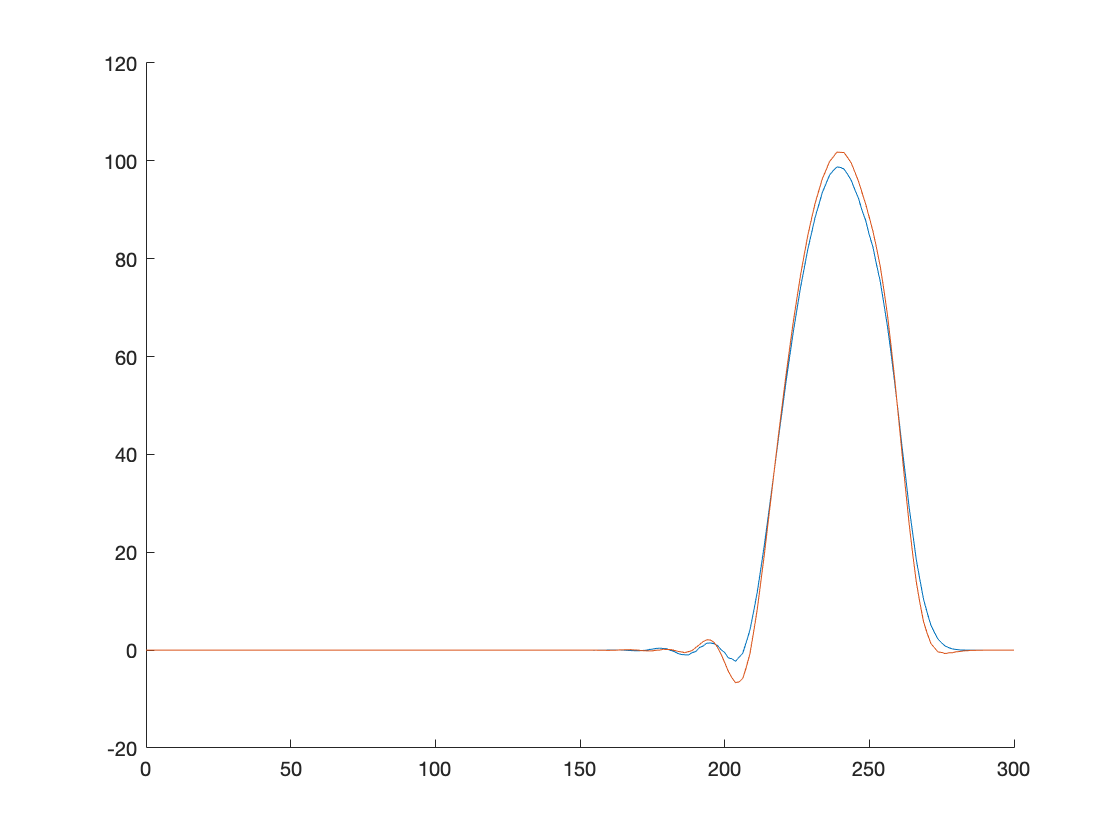

residual = 11.7838
residual = 16.5288


dt = 1;
T = 160;
Y = repmat(y, T+1, 1);
g = zeros(size(Y));
Z1 = multilevel_parareal(Y, g, h, dt, @advection_explicit, @linear_restriction, @ave_update_prolongation, 16, 2);

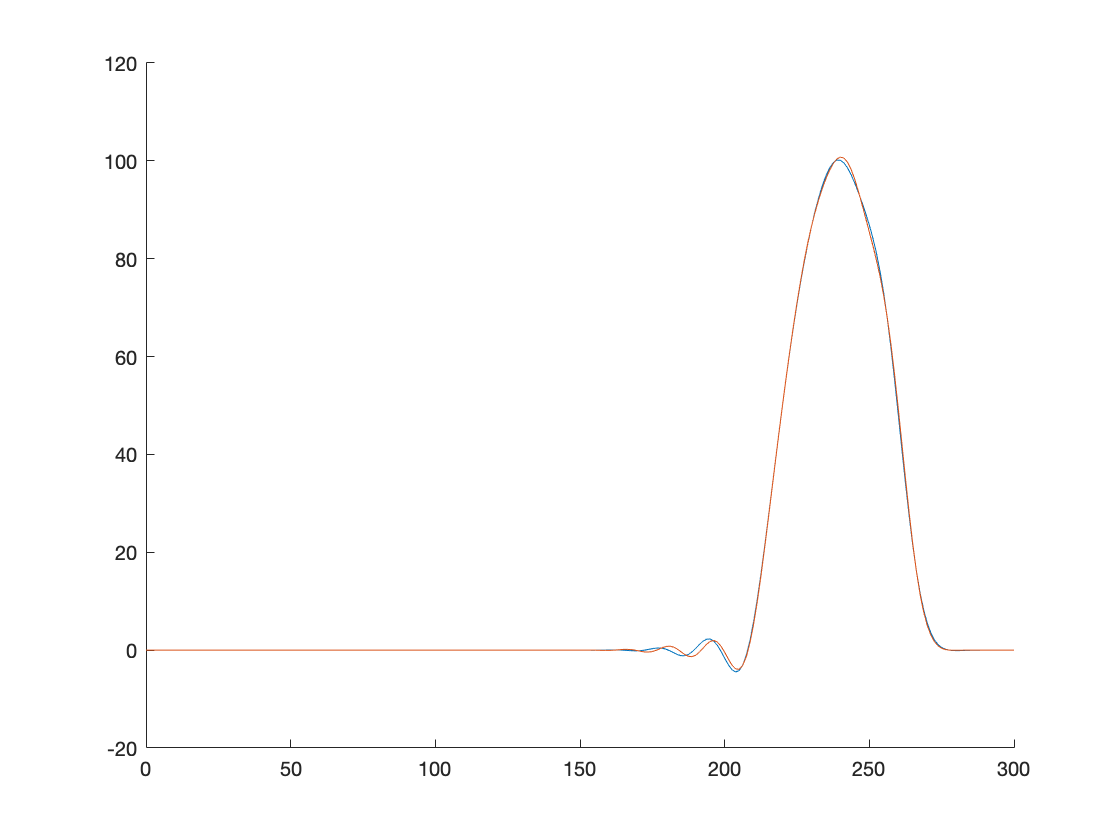

residual = 10.1981
residual = 4.0679


Z2 = multilevel_parareal(Y, g, h, dt, @advection_explicit, @linear_restriction, @spline_prolongation, 16, 2);

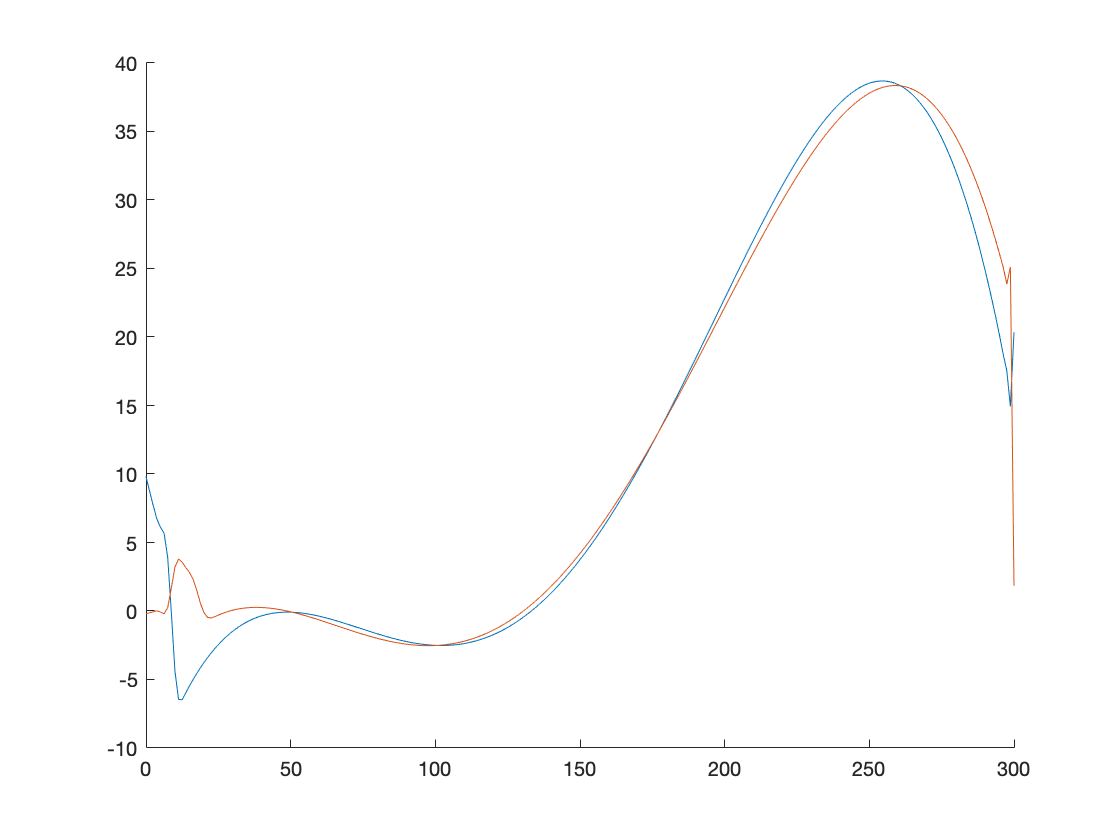

residual = 83.2516
residual = 15.7169


% Z3 = multilevel_parareal(Y, g, h, dt, @advection_explicit, @linear_restriction, @polyval_prolongation, 16, 2);

Z = Y;
for i = 1:T
    Z(i + 1, :) = Lax_Wendroff(Z(i, :), zeros(1,size(Y,2)), h, dt);
end

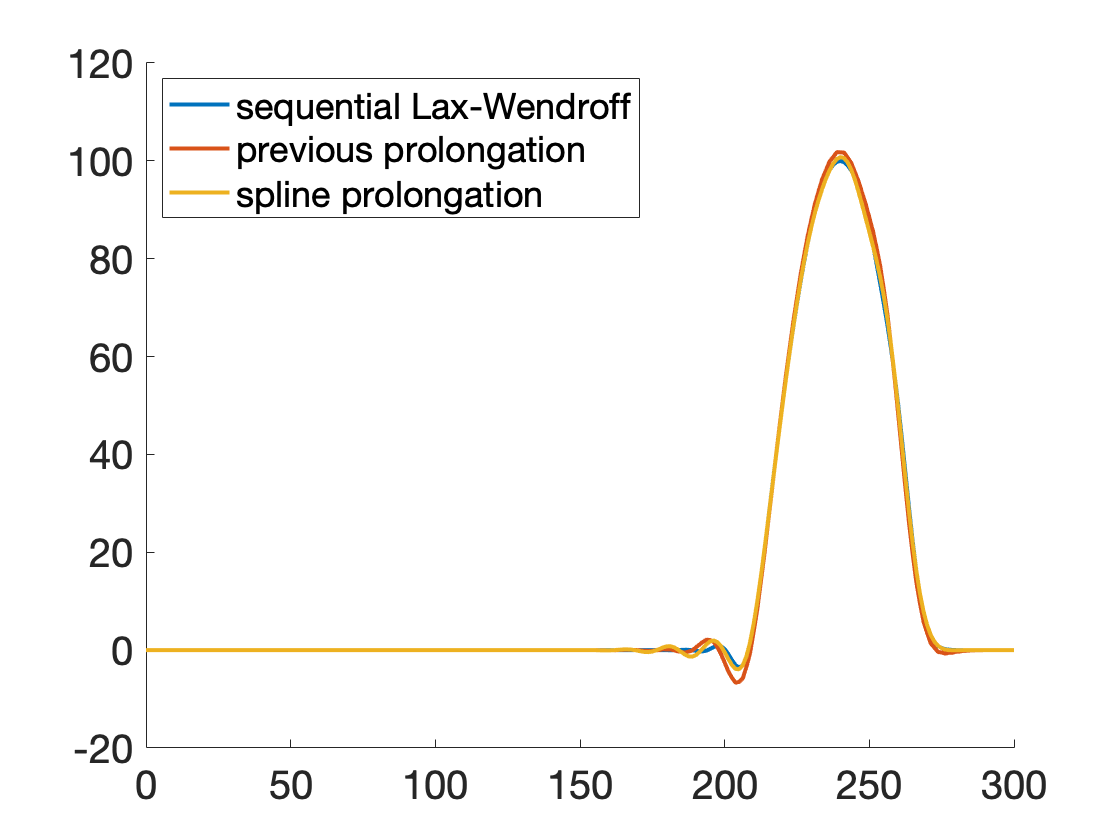

figure
set(gca, 'FontSize', 20)
hold on
plot(x, Z(end, :), "LineWidth", 2)
plot(x, Z1(end, :), "LineWidth", 2)
plot(x, Z2(end, :), "LineWidth", 2)
% plot(x, Z3(end, :), "LineWidth", 2)
legend({"sequential Lax-Wendroff", "previous prolongation", "spline prolongation"}, "Location", "northwest")
hold off

## MGRIT

h = 1.25;
dt = 1;
X = 300;
T = 160;
x = 0:h:X;
x = x(1:end-1);
l = length(x);
y = zeros(1, l);
for i = 1:length(x)
    if x(i) > 49.9 && x(i) < 110.1
        y(i) = 100*sin(pi*(x(i)-50)/60);
    end
end
Y = repmat(y, T+1, 1);
g = zeros(T+1, l);
for iter = 1:16
    Y = MGRIT_explicit(Y, g, h, dt, @advection_explicit, 16, 2);
    disp(strcat('error = ',string(norm(Z(end,:)-Y(end,:)))))
    error_MGRIT(iter) = norm(Z(end,:)-Y(end,:));
end

error =17.2709
error =7.8046
error =4.323
error =2.2147
error =0.92466
error =0.26538
error =0.048383
error =0.0042676
error =0.00016698
error =4.6781e-06
error =1.306e-07
error =4.3846e-09
error =1.7152e-10
error =4.5494e-12
error =6.0717e-14
error =0


## Multilevel parareal

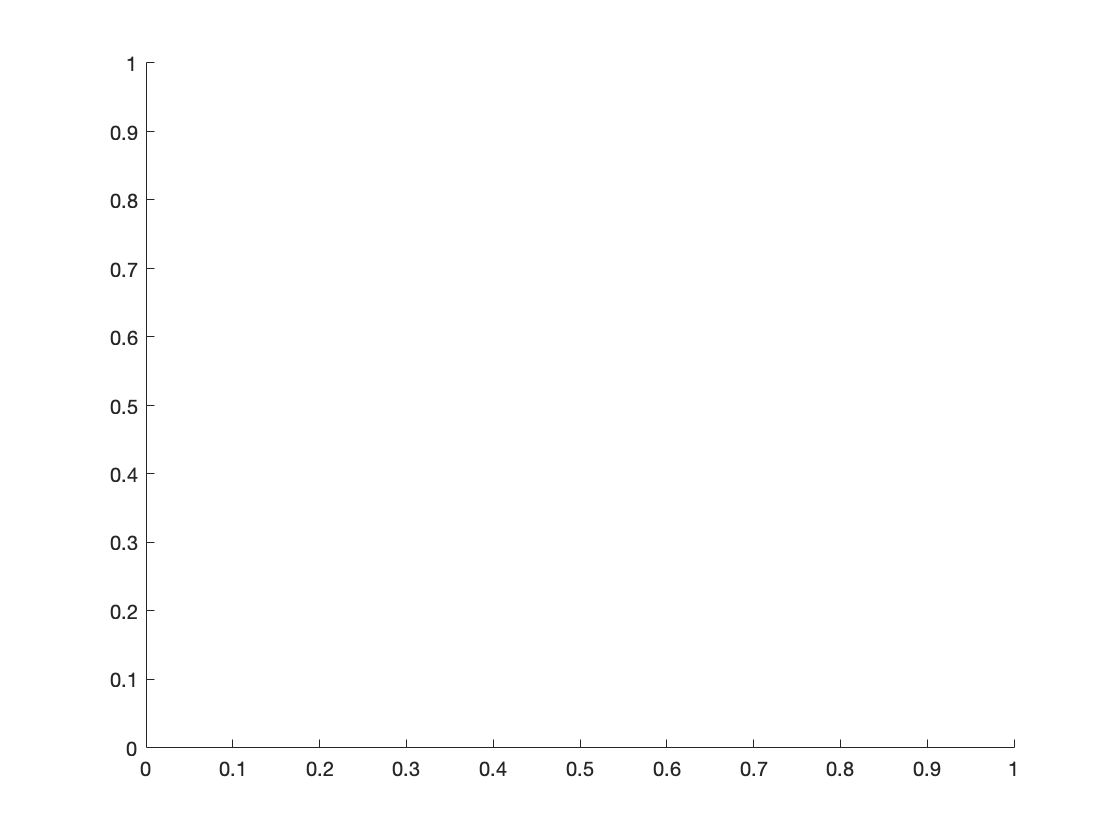

error = 9.1175
error = 6.0897
error = 4.2211
error = 2.9286
error = 1.9911
error = 1.3004
error = 0.82272
error = 0.50109
error = 0.28601
error = 0.15198
error = 0.075272
error = 0.033516
error = 0.012638
error = 0.0037464
error = 0.00068446
error = 0


h = 1.25;
dt = 1;
X = 300;
T = 160;
x = 0:h:X;
x = x(1:end-1);
l = length(x);
y = zeros(1, l);
for i = 1:length(x)
    if x(i) > 49.9 && x(i) < 110.1
        y(i) = 100*sin(pi*(x(i)-50)/60);
    end
end
Y = repmat(y, T+1, 1);
g = zeros(T+1, l);
[Y, error_mp] = multilevel_parareal(Y, g, h, dt, @advection_explicit, @linear_restriction, @spline_prolongation, 16, 2);